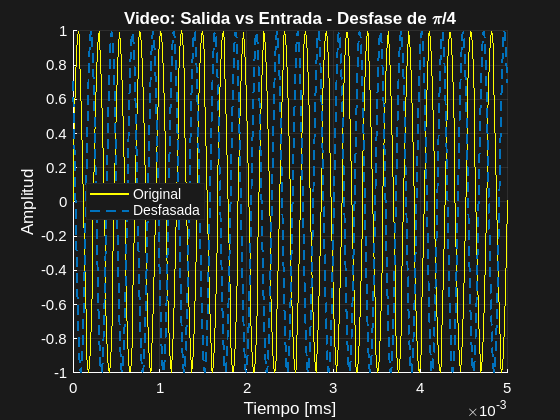

% Parámetros
fs = 100e6;            % Frecuencia de muestreo (100 kHz)
f = 4.2e6;               % Frecuencia de la señal (1 kHz)
phi = pi/4;            % Desfase en radianes
t = 0:1/fs:1e-2;       % Tiempo (10 ms)

% Señal original
x = sin(2*pi*f*t);

% Forma compleja
x_complex = exp(1j*2*pi*f*t);             % Representación en exponencial compleja
x_shifted_complex = x_complex * exp(1j*phi); % Aplicar desfase
x_shifted = real(x_shifted_complex);     % Parte real (senoidal desplazada)

% Figura: Señal en el tiempo con desfase de pi/2 (colores invertidos)
figure('Color', [0.1 0.1 0.1]); % Fondo de la figura gris oscuro
ax1 = gca;
set(ax1, 'Color', [0.1 0.1 0.1], ...      % Fondo de los ejes
        'XColor', 'w', ...               % Ejes blancos
        'YColor', 'w', ...
        'GridColor', [0.5 0.5 0.5], ...
        'GridAlpha', 0.2, ...
        'FontSize', 12);

hold on;
plot(t*1000, x, 'Color', [1 1 0], 'LineWidth', 1.5);            % Señal original en amarillo
plot(t*1000, x_shifted, '--', 'Color', [0 0.4470 0.7410], 'LineWidth', 1.5); % Señal desfasada en verde
xlim([0, 0.005])
xlabel('Tiempo [ms]', 'Color', 'w');
ylabel('Amplitud', 'Color', 'w');
title('Video: Salida vs Entrada - Desfase de \pi/4', 'Color', 'w');
legend('Original', 'Desfasada', 'TextColor', 'w', 'Location', 'best');
grid on;
% set(gcf, 'Units', 'Inches', 'Position', [0, 0, 10, 6]);
exportgraphics(gcf, 'audioR_entrada_vs_salida.png', 'BackgroundColor','current');

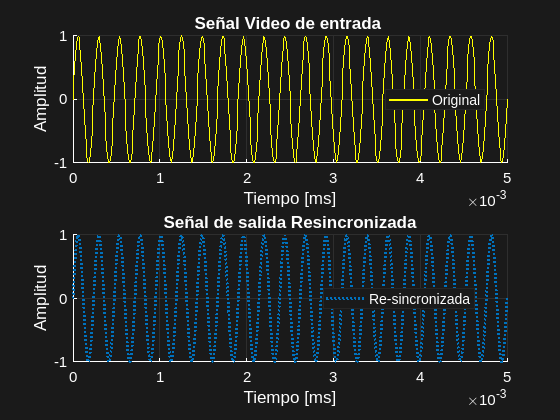


% % Parámetros
% fs = 100e3;            % Frecuencia de muestreo (100 kHz)
% f = 1e3;               % Frecuencia de la señal (1 kHz)
% phi = pi/2;            % Desfase en radianes
% t = 0:1/fs:1e-2;       % Tiempo (10 ms)
% 
% % Señal original
% x = sin(2*pi*f*t);
% 
% % Señal compleja
% x_complex = exp(1j*2*pi*f*t);
% x_shifted_complex = x_complex * exp(1j*phi);
% x_shifted = real(x_shifted_complex);

% Compensación de desfase
phi_sync = -phi - pi/2;
x_resynced_complex = x_shifted_complex * exp(1j * phi_sync);
x_resynced = real(x_resynced_complex);

% Figura con subplots
figure('Color', [0.1 0.1 0.1]);

% Primer subplot: Señal original y desfasada
subplot(2,1,1);
ax1 = gca;
set(ax1, 'Color', [0.1 0.1 0.1], ...
         'XColor', 'w', 'YColor', 'w', ...
         'GridColor', [0.5 0.5 0.5], 'GridAlpha', 0.2, ...
         'FontSize', 12);

hold on;
plot(t*1000, x, 'Color', [1 1 0], 'LineWidth', 1.5);           % Original en amarillo
xlabel('Tiempo [ms]', 'Color', 'w');
xlim([0, 0.005])
ylabel('Amplitud', 'Color', 'w');
title('Señal Video de entrada ', 'Color', 'w');
legend('Original', 'TextColor', 'w', 'Location', 'best');
grid on;

% Segundo subplot: Original y resincronizada
subplot(2,1,2);
ax2 = gca;
set(ax2, 'Color', [0.1 0.1 0.1], ...
         'XColor', 'w', 'YColor', 'w', ...
         'GridColor', [0.5 0.5 0.5], 'GridAlpha', 0.2, ...
         'FontSize', 12);

hold on;
% plot(t*1000, x, 'Color', [1 1 0], 'LineWidth', 1.5);           % Original en amarillo
plot(t*1000, x_resynced, ':', 'Color', [0 0.4470 0.7410], 'LineWidth', 2); % Resincronizada en cian claro
xlim([0, 0.005])
xlabel('Tiempo [ms]', 'Color', 'w');
ylabel('Amplitud', 'Color', 'w');
title('Señal de salida Resincronizada', 'Color', 'w');
legend('Re-sincronizada', 'TextColor', 'w', 'Location', 'best');
grid on;
% set(gcf, 'Units', 'Inches', 'Position', [0, 0, 10, 6]);
exportgraphics(gcf, 'senal_resincronizada.png', 'BackgroundColor','current');